clear

addpath("functions\")

#### Add defect to plate

Model = myModel;
freqs = [1000 2500 3000 10000]; % (Hz)
mesh_size = 4; % 1:finest 9:coarsest

global defects
defects = {};

Model = ComsolInterface('Build', Model);

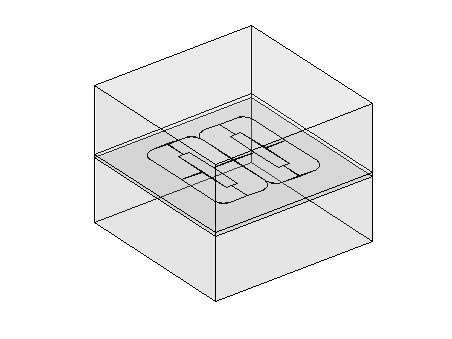


% ComsolInterface('AddCircularDefect', Model, -0.008, -0.008, 0.004,         0, -0.001)
% ComsolInterface('AddCircularDefect', Model,  0.008, -0.008, 0.004,         0, -0.002)
% ComsolInterface('AddCircularDefect', Model,  0.008,  0.008, 0.004,    -0.001, -0.003)
% ComsolInterface('AddCircularDefect', Model, -0.008,  0.008, 0.004,    -0.002, -0.003)

figure
ComsolInterface('PlotGeometry', Model)

#### Compute fields

thickness = 0;
for k = 1:length(Model.layers)-1
    thickness = thickness + Model.layers{k}.thickness;
end

B_data = zeros(length(freqs), size(Model.sensors.positions,2));
for i = 1:length(freqs)
    tic
    ComsolInterface('Solve', Model, freqs(i), mesh_size);
    fprintf("Solve %g Hz ec took %.2f seconds\n", freqs(i), toc)

    [Jx,Jy,gauss] = ComsolInterface('EvaluateField', Model, {'Jx' 'Jy'});
    mask = -thickness < gauss.z & gauss.z < 0;
    J = [Jx(mask); Jy(mask); zeros(1,sum(mask))];
    r = [gauss.x(mask); gauss.y(mask); gauss.z(mask)];
    dv = gauss.dv(mask);
    mu0_over_4pi = 1e-7;

    for j = 1:size(Model.sensors.positions,2)
        r_s = Model.sensors.positions(:,j);
        delta_r = r_s - r;
        Bec = mu0_over_4pi * cross(J, delta_r ./ vecnorm(delta_r).^3) .* dv;
        Bec = sum(Bec, 2);

        Bs = Model.coil.B(r_s(1), r_s(2), r_s(3));

        B_data(i,j) = dot(Bs + Bec, Model.sensors.axes(:,j));        
    end

    % visualize eddy current distribution
    x = linspace(-30e-3, 30e-3, 301);
    [x,y,z] = ndgrid(x, x, -0.5e-3);    
    normJ = ComsolInterface('EvaluateField', Model, 'normJ', x,y,z);

    figure
    surf(x, y, normJ, 'LineStyle','none')
    view(2)
    axis square
    colorbar
    xlabel('$x$ (m)', 'Interpreter','latex')
    ylabel('$y$ (m)', 'Interpreter','latex')
    title(strcat('$\|\textbf{J}\|$ (A/m$^2$) @ ',string(freqs(i)),' Hz'), 'Interpreter','latex')
end

clear thickness i j k Jx Jy Jz gauss J r dv mu0_over_4pi r_s delta_r Bec Bs normJ

#### Export sensor data

fname = sprintf('data/B_%s.txt', datetime('now','Format','MMdd-HHmm'));

fid = fopen(fname, 'w');

for i = 1:length(defects)
    fprintf(fid, '%% defect %s\n', jsonencode(defects{i}));
end
for i = 1:length(freqs)
    fprintf(fid, '%% frequency %g Hz\n', freqs(i));
    fprintf(fid, '%s\n', num2str(B_data(i,:)));
end

fclose(fid);

clear fname fid i